clear, close all, clc

Det ønskes at vide, om flyderaten for et molekyle påvirker uniformiteten af ridsningen af et silicium-stykke. Tre forskellige flyderater er anvendt, og uniformiteten i procent for 6 observationer findes.

load('dataset_problem_13_6.mat')

Opgave a) Påvirker molekylets flyderate ridsningens uniformitet? Konstruer boks-plots for at sammenligne faktor-niveauerne og udfør en variansanalyse. Brug α = 0,05.

alpha = 0.05

alpha = 0.0500

% Der er 3 stikprøver
a = 3

a = 3


Y1 = data(:,1);
Y2 = data(:,2);
Y3 = data(:,3);

% n1 = n2 = n3 = 6
n = 6

n = 6

N = a*n

N = 18

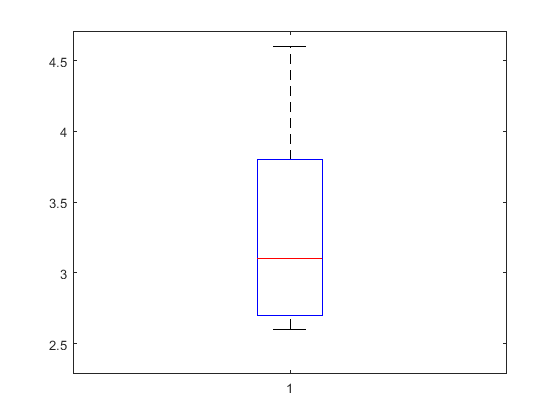


boxplot(Y1)

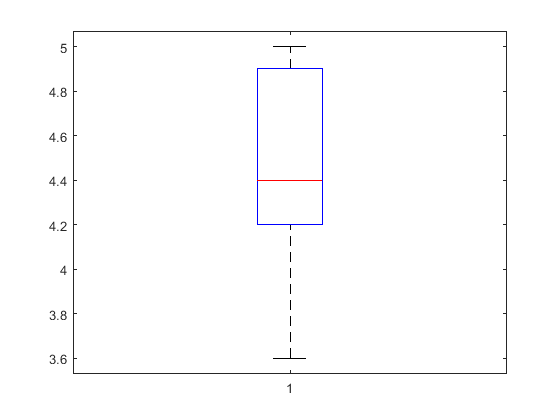

boxplot(Y2)

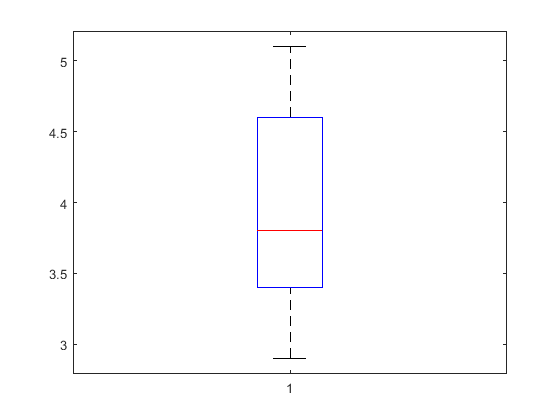

boxplot(Y3)

% Den ene (Y3) ligger i midten, mens de to andre
% er i ekstremerne (Y2 høj, Y1 lav)

Y1bar = 1/n * sum(Y1)

Y1bar = 3.3167

Y2bar = 1/n * sum(Y2)

Y2bar = 4.4167

Y3bar = 1/n * sum(Y3)

Y3bar = 3.9333

Yallbar = 1/(N) * (sum(Y1)+sum(Y2)+sum(Y3))

Yallbar = 3.8889

Ybars = [Y1bar Y2bar Y3bar];

SST = 0;
for i = 1:a
    for j = 1:n
        SST = SST + (data(j,i)-Yallbar)^2;
    end
end
SST

SST = 11.2778


SSW = 0;
for i = 1:a
    for j = 1:n
        SSW = SSW + (data(j,i)-Ybars(1,i))^2;
    end
end
SSW

SSW = 7.6300


SSB = 0;
for i = 1:a
    SSB = SSB + n*(Ybars(1,i)-Yallbar)^2;
end
SSB

SSB = 3.6478


S_T_squared = SST/(N-1)

S_T_squared = 0.6634

S_W_squared = SSW/(N-a)

S_W_squared = 0.5087

S_B_squared = SSB/(a-1)

S_B_squared = 1.8239


f0 = S_B_squared/S_W_squared

f0 = 3.5856


P = 1 - fcdf(f0, a-1, N-a)

P = 0.0534

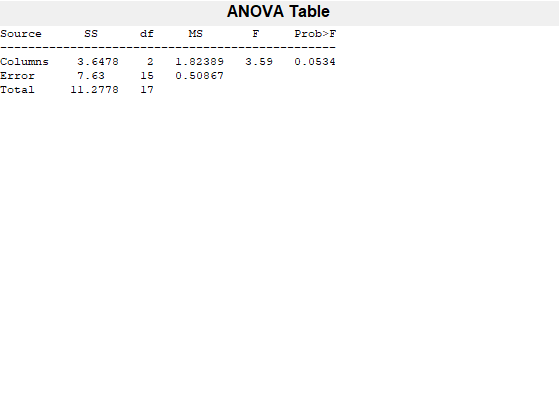

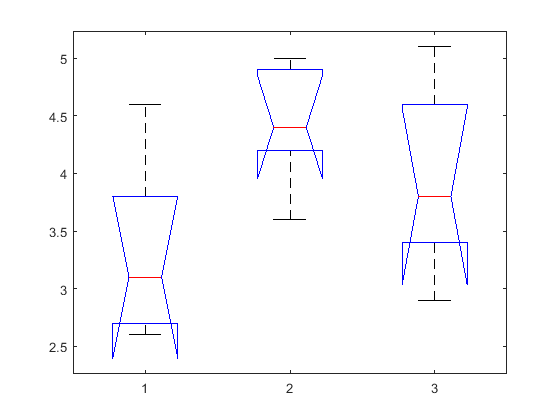

P = 0.0534


% Idet P = 5,34%, bliver nulhypotesen ikke forkastet
% med signifikansniveau alpha = 5%
% Det må derfor knebent accepteres, at
% middelværdierne er identiske.

% Alternativ metode:
P = anova1(data)

Opgave b) Viser residualerne et problem med de underliggende antagelser?

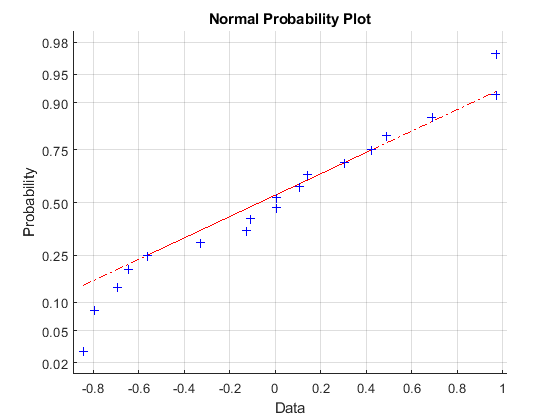

R = ANOVAResiduals(data);
np = [R(:,1);R(:,2);R(:,3)];
normplot(np)

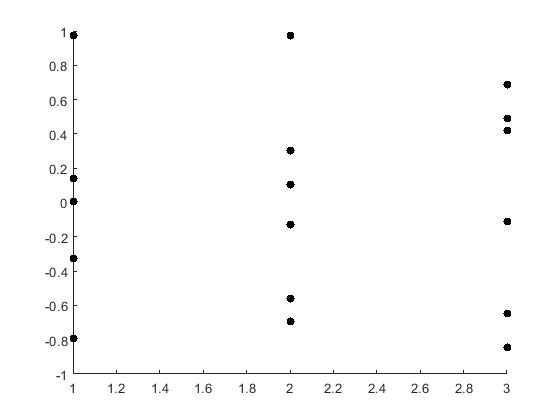

figure(4)
hold on
sz = size(R(:,1));
scatter(ones(sz),R(:,1),'filled','k')
scatter(2*ones(sz),R(:,2),'filled','k')
scatter(3*ones(sz),R(:,3),'filled','k')


% Begge plots virker helt fine, selvom halerne er
% lidt skæve.